# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\TimeEst EEG-CG\RawData_new'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = false;  
Deci.PCom               = true;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\TimeEst EEG-CG\TimeEst_Processed'];    

## 1. Trial Definitions

Deci.DT.Starts     = {10};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {11};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[28 37]};

Deci.DT.Locks      = [27];
Deci.DT.Toi        = [-.5 1.5]; 

## 2. PreProcessing Steps

Deci.PP = [];
Deci.PP.filter.bpfreq = [1 30];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';
Deci.PP.More.channel = {'FCz'};

Deci.ICA.do = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.Manual_Trial_Rejection = false;
Deci.Art.ShowArt =  false;

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

%CDA
  
Deci.Analysis.Channels = {'FCz'};
Deci.Analysis.Locks         = [1];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Feedback Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.Conditions    = {[28] [37]};

Deci.Analysis.CondTitle     = {'Correct' 'Incorrect'};
Deci.Analysis.Version = [Deci.Folder.Version];
Deci.Analysis.ERP.do  = true;

Deci.Analysis.Toilim = [-2 3];
Deci.Analysis.Toi = [-.5 1.5];

## 5. Plotting

Running Deci for 14 subjects
 
----------------------
 
Plotting ERP
Loading Plottor for Subject #1: TimeEst_EEGTest_John
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_appendtimelock" took 0 seconds
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_appendtimelock" took 0 seconds
Loading Plottor for Subject #2: TimeEst_EEG_039CG
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_appendtimelock" took 0 seconds
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_appendtimelock" took 0 seconds
Loading Plottor for Subject #3: TimeEst_EEG_046CG
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_appendtimelock" took 0 seconds
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_appendtimelock" took 0 seconds
Loading Plottor for Subject #4: TimeEst_EEG_050PS
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_app

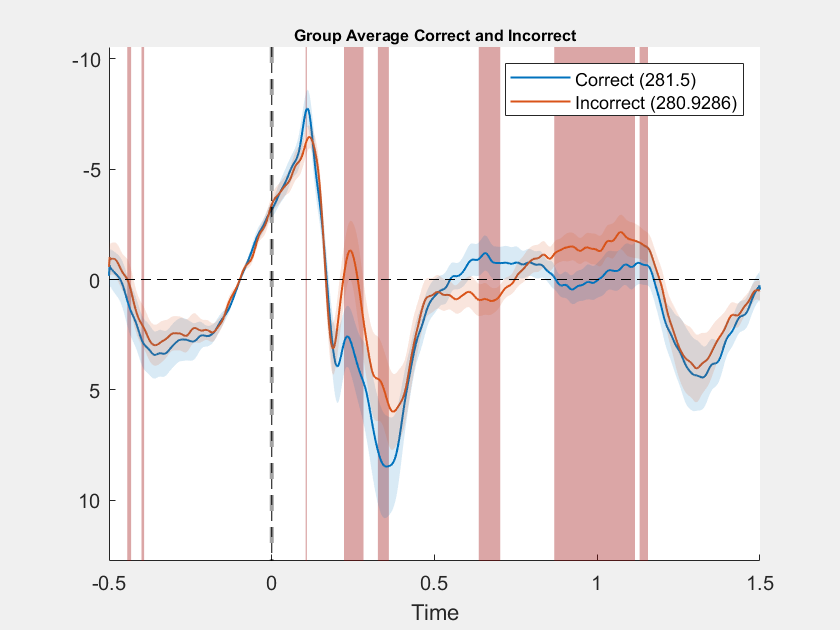

the call to "ft_singleplotER" took 0 seconds


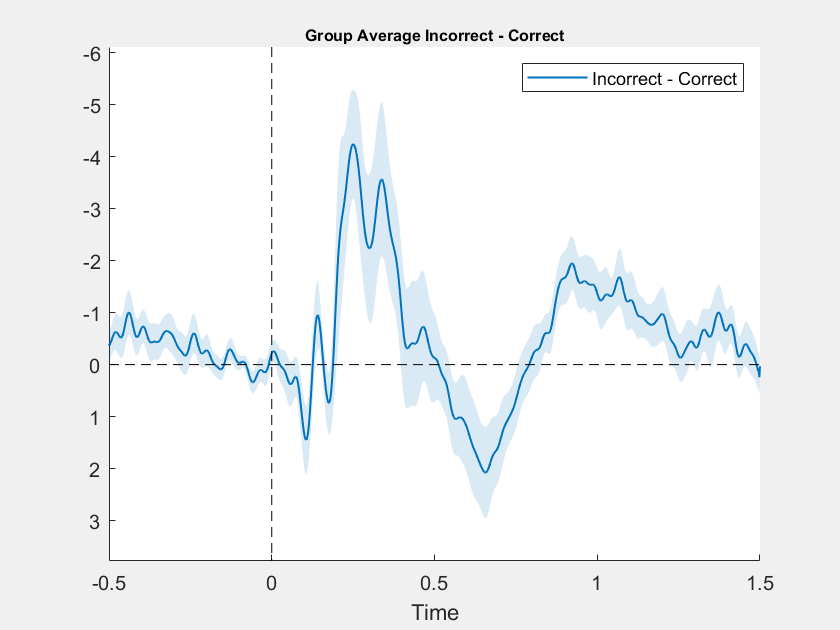

the call to "ft_singleplotER" took 0 seconds


Deci.Plot.Version = [Deci.Analysis.Version];
Deci.Plot.Figures      = [true true];
Deci.Plot.Math         = {'x2 - x1'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2] [3]};                   % Cell array of Condition Index for each figure

Deci.Plot.Title        = {'Correct and Incorrect' 'Incorrect - Correct'};          % Title for each figure
Deci.Plot.Subtitle     = {{'Correct' 'Incorrect'} {'Incorrect - Correct'}};     % Cell array of strings of subtitles for each Condition

Deci.Plot.BslRef = 'Feedback Onset';
Deci.Plot.Lock =   'Feedback Onset';
Deci.Plot.Bsl     = [-.2 0];

%Deci.Run.Freq =false;
Deci.Run.ERP =true;
Deci.Run.Extra = false;

Deci.Plot.GrandAverage = true;

Deci.Plot.Topo.do    =false;
Deci.Plot.Topo.Toi     =[.2 .4];                   % Time of Interest
Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Wire.do    =true;
Deci.Plot.Wire.Channel =   {'FCz'};            % Channel of Interest
Deci.Plot.Wire.Toi     = [-.5 1.5];                   % Time of Interest

Deci.Plot.Bar.do    =false;
Deci.Plot.Bar.Toi     = [.2 .4];                    % Time of Interest
Deci.Plot.Bar.Channel =  {'FCz'};            % Channel of Interest

Deci.Plot.Stat.do = true; % Will only work if for large subject pools
if Deci.Plot.Stat.do
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
    Deci.Plot.Stat.correctm = 'no';
end


Deci_Backend(Deci);